# 第五章部分习题的MATLAB代码

5-1、5-2、5-3、5-4、5-6、5-9、5-18

## 5-4 离散系统与连续系统的频率特性

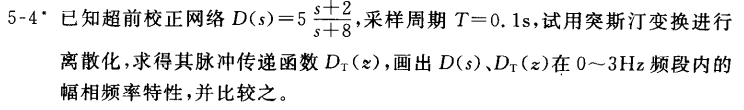

### 1对给定系统进行离散化，得到控制器的离散传递函数

T=0.1;
D=5*tf([1 2],[1 8]);
Dz=c2d(D,T,'tustin')

Dz =
 
  3.929 z - 3.214
  ---------------
    z - 0.4286
 
Sample time: 0.1 seconds
Discrete-time transfer function.



### 2绘制0到3Hz内的幅相频率特性曲线

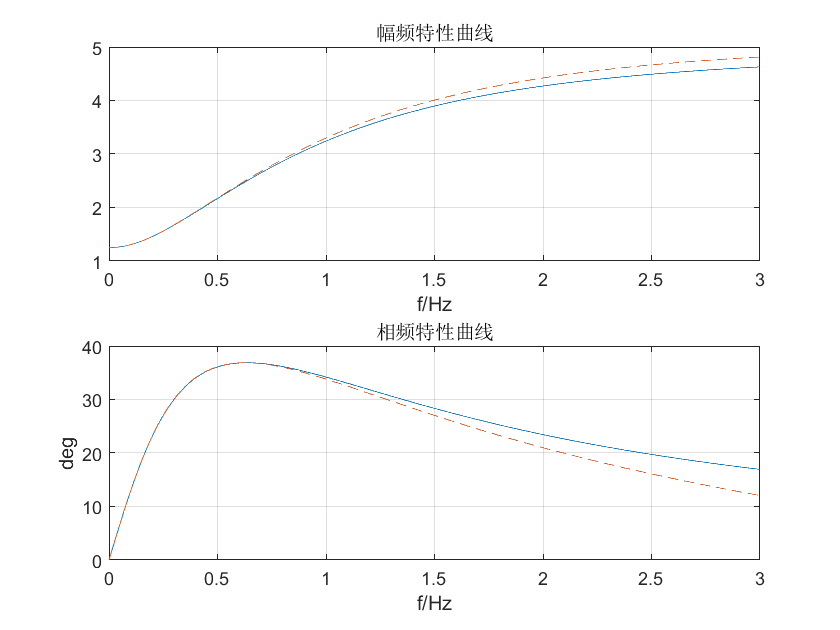

f=linspace(0,3,1000);
[mag,phase]=bode(D,f*2*pi);
[magd,phased]=bode(Dz,f*2*pi);
subplot(2,1,1);
plot(f,mag(:),'-',f,magd(:),'--');
title('幅频特性曲线');xlabel('f/Hz');
grid on;
subplot(2,1,2);
plot(f,phase(:),'-',f,phased(:),'--');
title('相频特性曲线');xlabel('f/Hz');ylabel('deg')
grid on;

## 5-9 离散系统的根轨迹

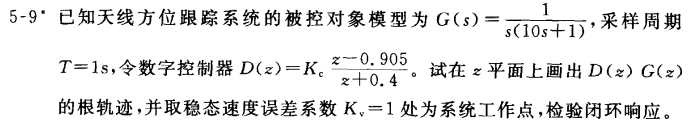

### 1绘制开环传递函数的根轨迹

figure();
G=tf(1,conv([1 0],[10 1]));
T=1;
D0=zpk(0.905,-0.4,1,T);
Gz=c2d(G,T);
DG=series(D0,Gz);
[p,z]=pzmap(DG)

p =     1.0000
    0.9048
   -0.4000


z =    -0.9672
    0.9050


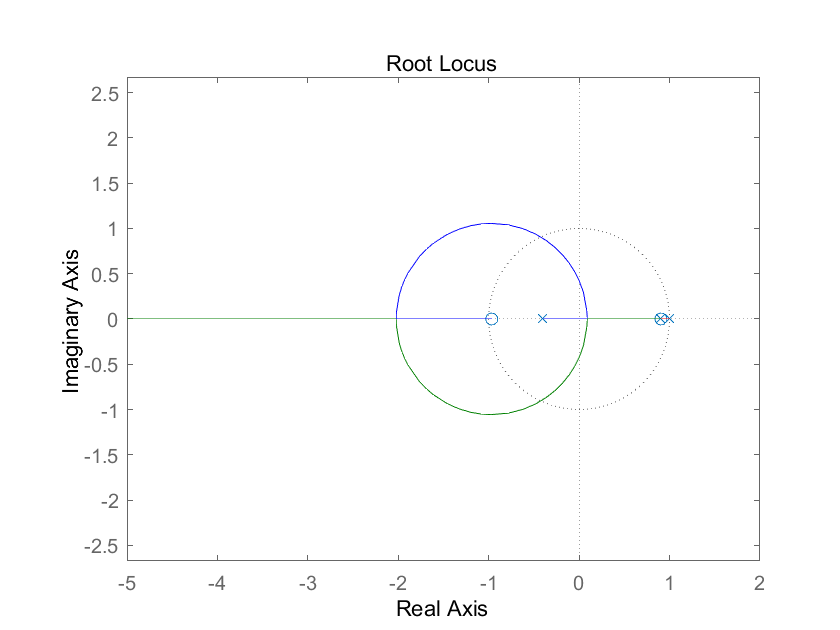

rlocusplot(DG);%绘制开环传递函数根轨迹图
axis equal

### 2计算满足要求的增益值

通过计算可知速度误差系数为1时的K值,由此可以计算出对应根轨迹：


$$K_v =1=\frac{1}{T}\underset{z\to 1}{lim} \left(z-1\right)D\left(z\right)G\left(z\right)$$

$$={{\left(0.0484K_c \frac{\left(z+0.9669\right)\left(z-0.905\right)}{\left(z-0.9048\right)\left(z+0.4\right)}\right|}}_{z=1}$$


[num,den]=zp2tf(cell2mat(DG.Z),DG.P{1}(2:3),DG.K);
z=sym('z');
DGsym=poly2sym(num,z)/poly2sym(den,z);
DGfun=symfun(DGsym,z);
Kc=Kv/DGfun(1);
fprintf('Kv=%g*Kc Kc=%g',DGfun(1),double(Kc));

Kv=0.0678571*Kc Kc=14.7368

### 3绘制相应的阶跃响应曲线

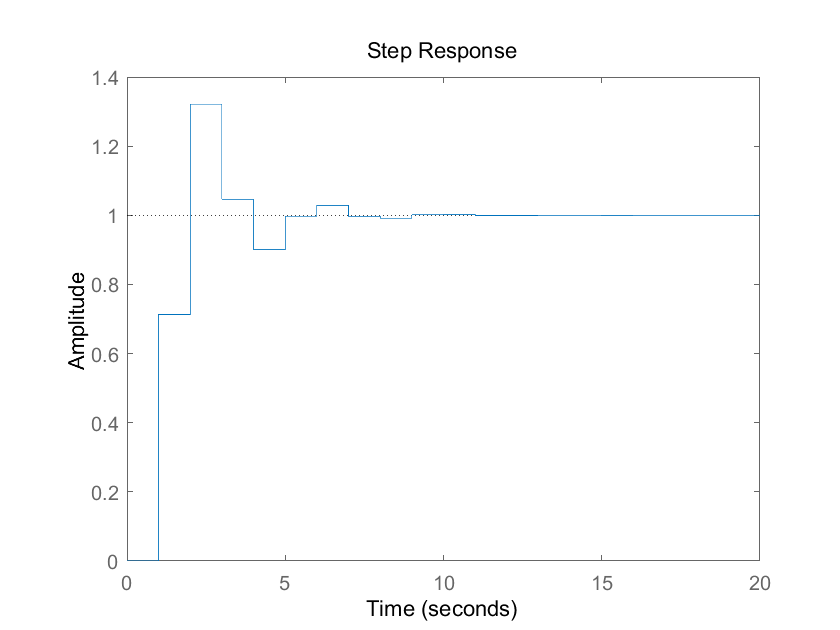

Kc=14.7372;
r=rlocus(DG,Kc);
Phi=feedback(Kc*DG,1);
stepplot(Phi)

## 5-18

该题目似乎不适合MATLAB解答

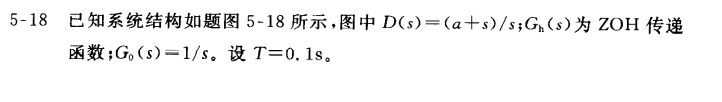

s=tf('s');
G0=1/s;
T=0.1;
G0z=c2d(G0,T,'zoh');

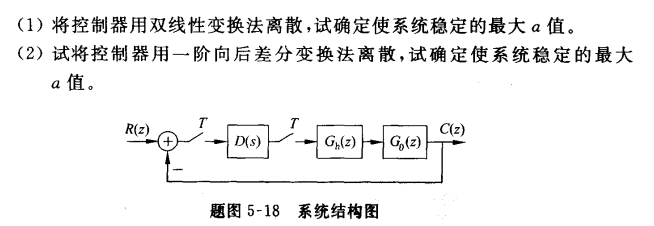

%将传递函数转化为数学符号表达式方便运算
[num,den]=tfdata(G0z);
syms a z;
G=poly2sym(num,z)/poly2sym(den,z);
D=@(s)((a+s)/s);

### (1) 双线性变换

#### a) 二阶离散系统的特征方程

%代数运算 双线性变换
s=2/T*(z-1)/(z+1);
DG=D(s)*G;
[num,den]=numden(simplify(DG));%代数表达式：开环传递函数
c=coeffs(num+den,z);
delta=poly2sym(flip(c)/c(end),z);%最高次幂归一化
delta=symfun(delta,z);%特征方程左边部分
display(delta(z)==0);

$$ans = z^{2}+\left(\frac{a}{200}-\frac{19}{10}\right)\,z+\frac{a}{200}+\frac{9}{10}=0$$

#### b) 二阶离散系统稳定的充分必要条件

con1=abs(delta(0))<1;
con2=delta(1)>0;
con3=delta(-1)>0;
conds1=[con1,con2,con3]

$$conds1 = \left(\begin{array}{ccc} \left|\frac{a}{200}+\frac{9}{10}\right|<1 & 0<\frac{a}{100} & 0<\frac{19}{5} \end{array}\right)$$

#### c) 运算结果

sol = solve(conds1, a, 'ReturnConditions', true);
sol.conditions

$$ans = 0<x\wedge x<20$$

### (2) 一阶向后差分法

%代数运算 一阶向后差分
s=(1-z^(-1))/T;
DG=D(s)*G;
[num,den]=numden(simplify(DG));%代数表达式：开环传递函数
c=coeffs(num+den,z);
delta=poly2sym(flip(c)/c(end),z);%最高次幂归一化
delta=symfun(delta,z);%特征方程左边部分
display(delta(z)==0);

$$ans = z^{2}+\left(\frac{a}{100}-\frac{19}{10}\right)\,z+\frac{9}{10}=0$$

con1=abs(delta(0))<1;
con2=delta(1)>0;
con3=delta(-1)>0;
conds2=[con1,con2,con3]

$$conds2 = \left(\begin{array}{ccc} \frac{9}{10}<1 & 0<\frac{a}{100} & 0<\frac{19}{5}-\frac{a}{100} \end{array}\right)$$

sol = solve(conds2, a, 'ReturnConditions', true);
sol.conditions

$$ans = 0<x\wedge x<380$$